% --- SETUP ---

file_paths = {
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\healthy.set'
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\mci.set'
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\ad.set'
};

group_names = {'Healthy', 'MCI', 'AD'};
odor_names = {'Chocolate', 'Rose'};
odor_codes = [5, 6]; % Event codes for odors

% STFT
win_sec = 1;        % Window length in seconds
overlap_ratio = 0.9; % 90% overlap
theta_band = [4 8];  % Theta frequency range
gamma_band = [30 50]; % Gamma frequency range
channel_to_analyze = 1;

all_theta = struct();
all_gamma = struct();
time_vectors = struct();

% --- PROCESS EACH GROUP ---
for group_idx = 1:length(file_paths)
    % Load EEG data
    EEG = pop_loadset(file_paths{group_idx});
    fs = EEG.srate;
    
    % Calculate STFT
    win_len = round(win_sec * fs);
    overlap_len = round(overlap_ratio * win_len);
    nfft = win_len;
    
    [~, F, ~] = spectrogram(EEG.data(channel_to_analyze, :, 1), win_len, overlap_len, nfft, fs);
    theta_idx = F >= theta_band(1) & F <= theta_band(2);
    gamma_idx = F >= gamma_band(1) & F <= gamma_band(2);
    
    trial_indices = struct();
    for o = 1:length(odor_codes)
        odor_code = odor_codes(o);
        trial_indices.(odor_names{o}) = find([EEG.epoch.eventtype] == odor_code);
    end
    
    % Process each odor
    for o = 1:length(odor_names)
        odor_name = odor_names{o};
        trials = trial_indices.(odor_name);
        
        if isempty(trials)
            warning('No trials found for %s in %s group', odor_name, group_names{group_idx});
            all_theta.(group_names{group_idx}).(odor_name) = NaN;
            all_gamma.(group_names{group_idx}).(odor_name) = NaN;
            time_vectors.(group_names{group_idx}).(odor_name) = NaN;
            continue;
        end
        
        theta_power = [];
        gamma_power = [];
        T_master = [];
        
        % Process each trial
        for t = 1:length(trials)
            trial_idx = trials(t);
            trial_data = EEG.data(channel_to_analyze, :, trial_idx);
            
            [S, F, T] = spectrogram(trial_data, win_len, overlap_len, nfft, fs);
            P = abs(S).^2;
            
            if isempty(T_master)
                T_master = T;
            end
            
            % Calculate band power
            theta_power(t,:) = mean(P(theta_idx, :), 1);
            gamma_power(t,:) = mean(P(gamma_idx, :), 1);
        end
        
        % Store results
        all_theta.(group_names{group_idx}).(odor_name) = mean(theta_power, 1);
        all_gamma.(group_names{group_idx}).(odor_name) = mean(gamma_power, 1);
        time_vectors.(group_names{group_idx}).(odor_name) = T_master;
    end
end

pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\healthy.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\mci.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\ad.set ...
eeg_checkset: recomputing the ICA activation matrix ...


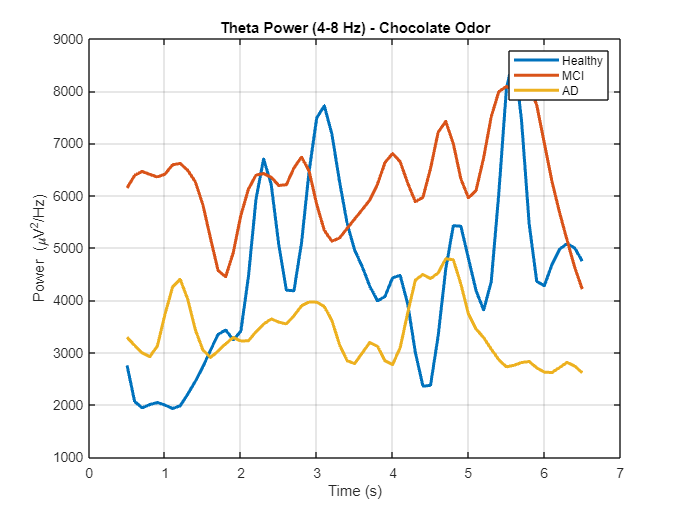

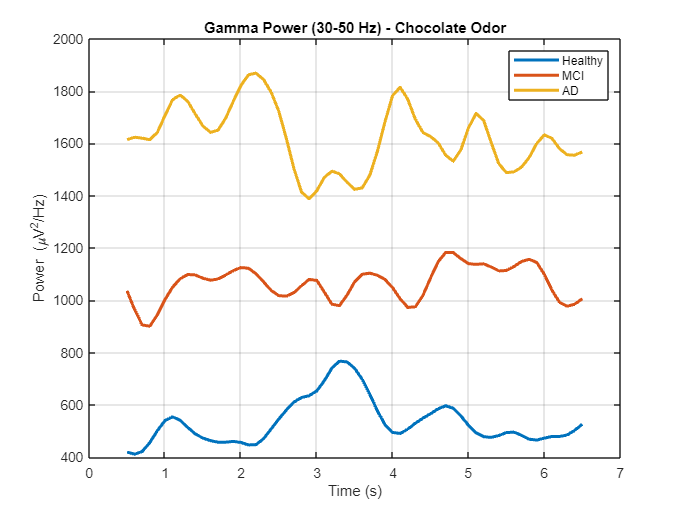

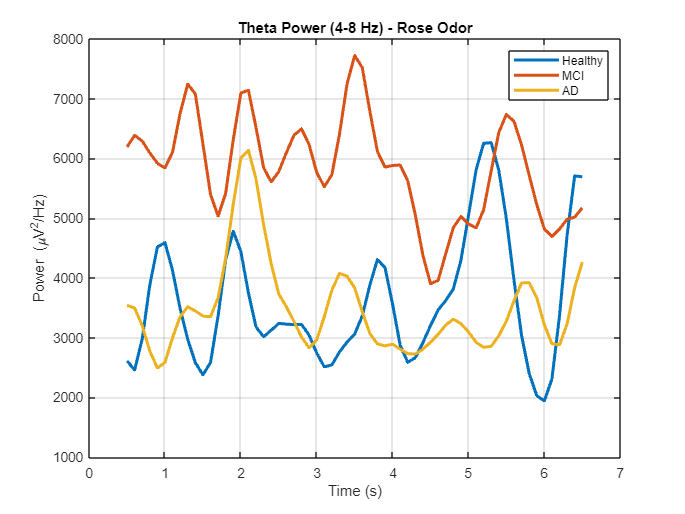

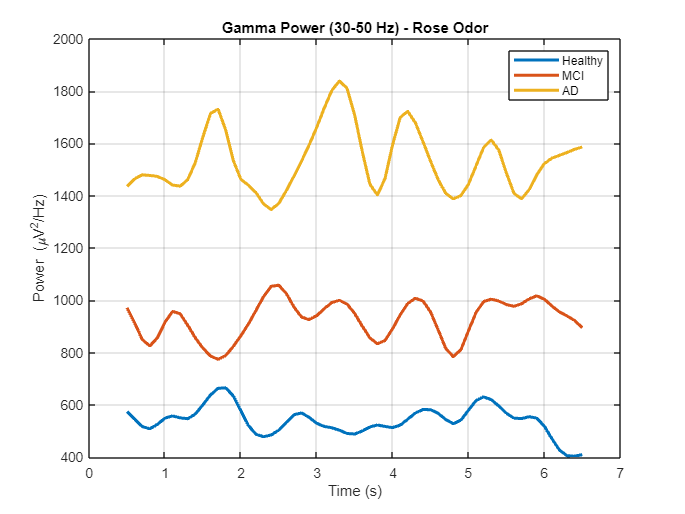


% --- PLOTTING ---
for o = 1:length(odor_names)
    odor_name = odor_names{o};
    
    figure('Name', ['Theta Power - ' odor_name], 'Position', [100 100 800 600]);
    hold on;
    
    for g = 1:length(group_names)
        group = group_names{g};
        if isfield(all_theta.(group), odor_name) && ~all(isnan(all_theta.(group).(odor_name)))
            plot(time_vectors.(group).(odor_name), all_theta.(group).(odor_name), ...
                'LineWidth', 2, 'DisplayName', group);
        end
    end
    
    title(['Theta Power (4-8 Hz) - ' odor_name ' Odor']);
    xlabel('Time (s)');
    ylabel('Power (\muV^2/Hz)');
    legend('show');
    grid on;
    box on;
    
    figure('Name', ['Gamma Power - ' odor_name], 'Position', [100 100 800 600]);
    hold on;
    
    for g = 1:length(group_names)
        group = group_names{g};
        if isfield(all_gamma.(group), odor_name) && ~all(isnan(all_gamma.(group).(odor_name)))
            plot(time_vectors.(group).(odor_name), all_gamma.(group).(odor_name), ...
                'LineWidth', 2, 'DisplayName', group);
        end
    end
    
    title(['Gamma Power (30-50 Hz) - ' odor_name ' Odor']);
    xlabel('Time (s)');
    ylabel('Power (\muV^2/Hz)');
    legend('show');
    grid on;
    box on;
end

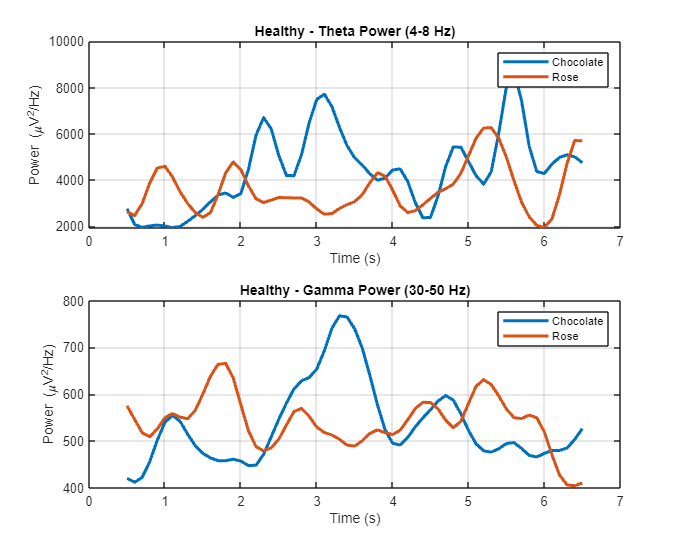

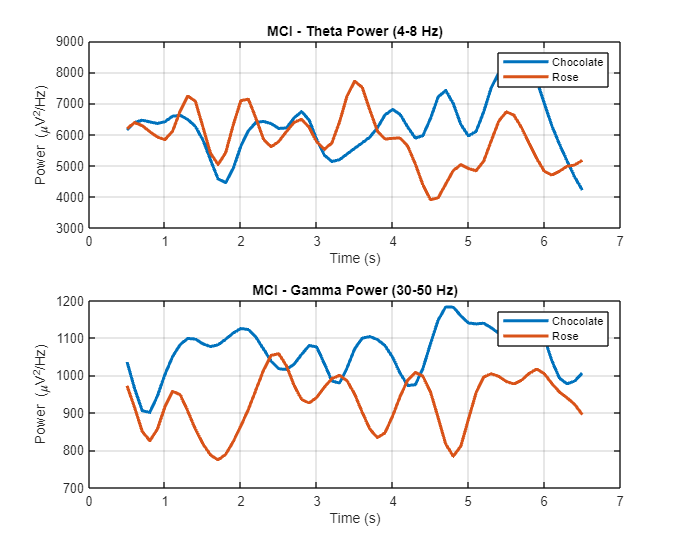

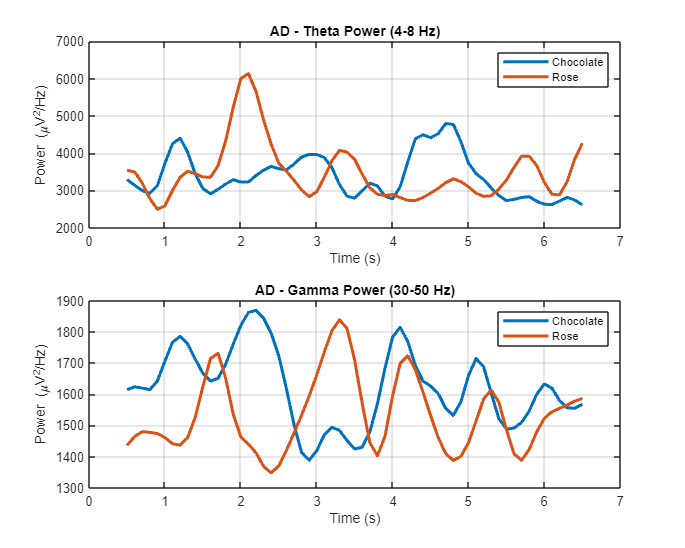


for g = 1:length(group_names)
    group = group_names{g};
    
    if ~isfield(all_theta, group) || ~isfield(all_gamma, group)
        continue;
    end
    
    figure('Name', ['Power Analysis - ' group], 'Position', [100 100 1000 800]);
    
    subplot(2,1,1);
    hold on;
    for o = 1:length(odor_names)
        odor_name = odor_names{o};
        if isfield(all_theta.(group), odor_name) && ~all(isnan(all_theta.(group).(odor_name)))
            plot(time_vectors.(group).(odor_name), all_theta.(group).(odor_name), ...
                'LineWidth', 2, 'DisplayName', odor_name);
        end
    end
    title([group ' - Theta Power (4-8 Hz)']);
    xlabel('Time (s)');
    ylabel('Power (\muV^2/Hz)');
    legend('show');
    grid on;
    box on;
    
    subplot(2,1,2);
    hold on;
    for o = 1:length(odor_names)
        odor_name = odor_names{o};
        if isfield(all_gamma.(group), odor_name) && ~all(isnan(all_gamma.(group).(odor_name)))
            plot(time_vectors.(group).(odor_name), all_gamma.(group).(odor_name), ...
                'LineWidth', 2, 'DisplayName', odor_name);
        end
    end
    title([group ' - Gamma Power (30-50 Hz)']);
    xlabel('Time (s)');
    ylabel('Power (\muV^2/Hz)');
    legend('show');
    grid on;
    box on;
end